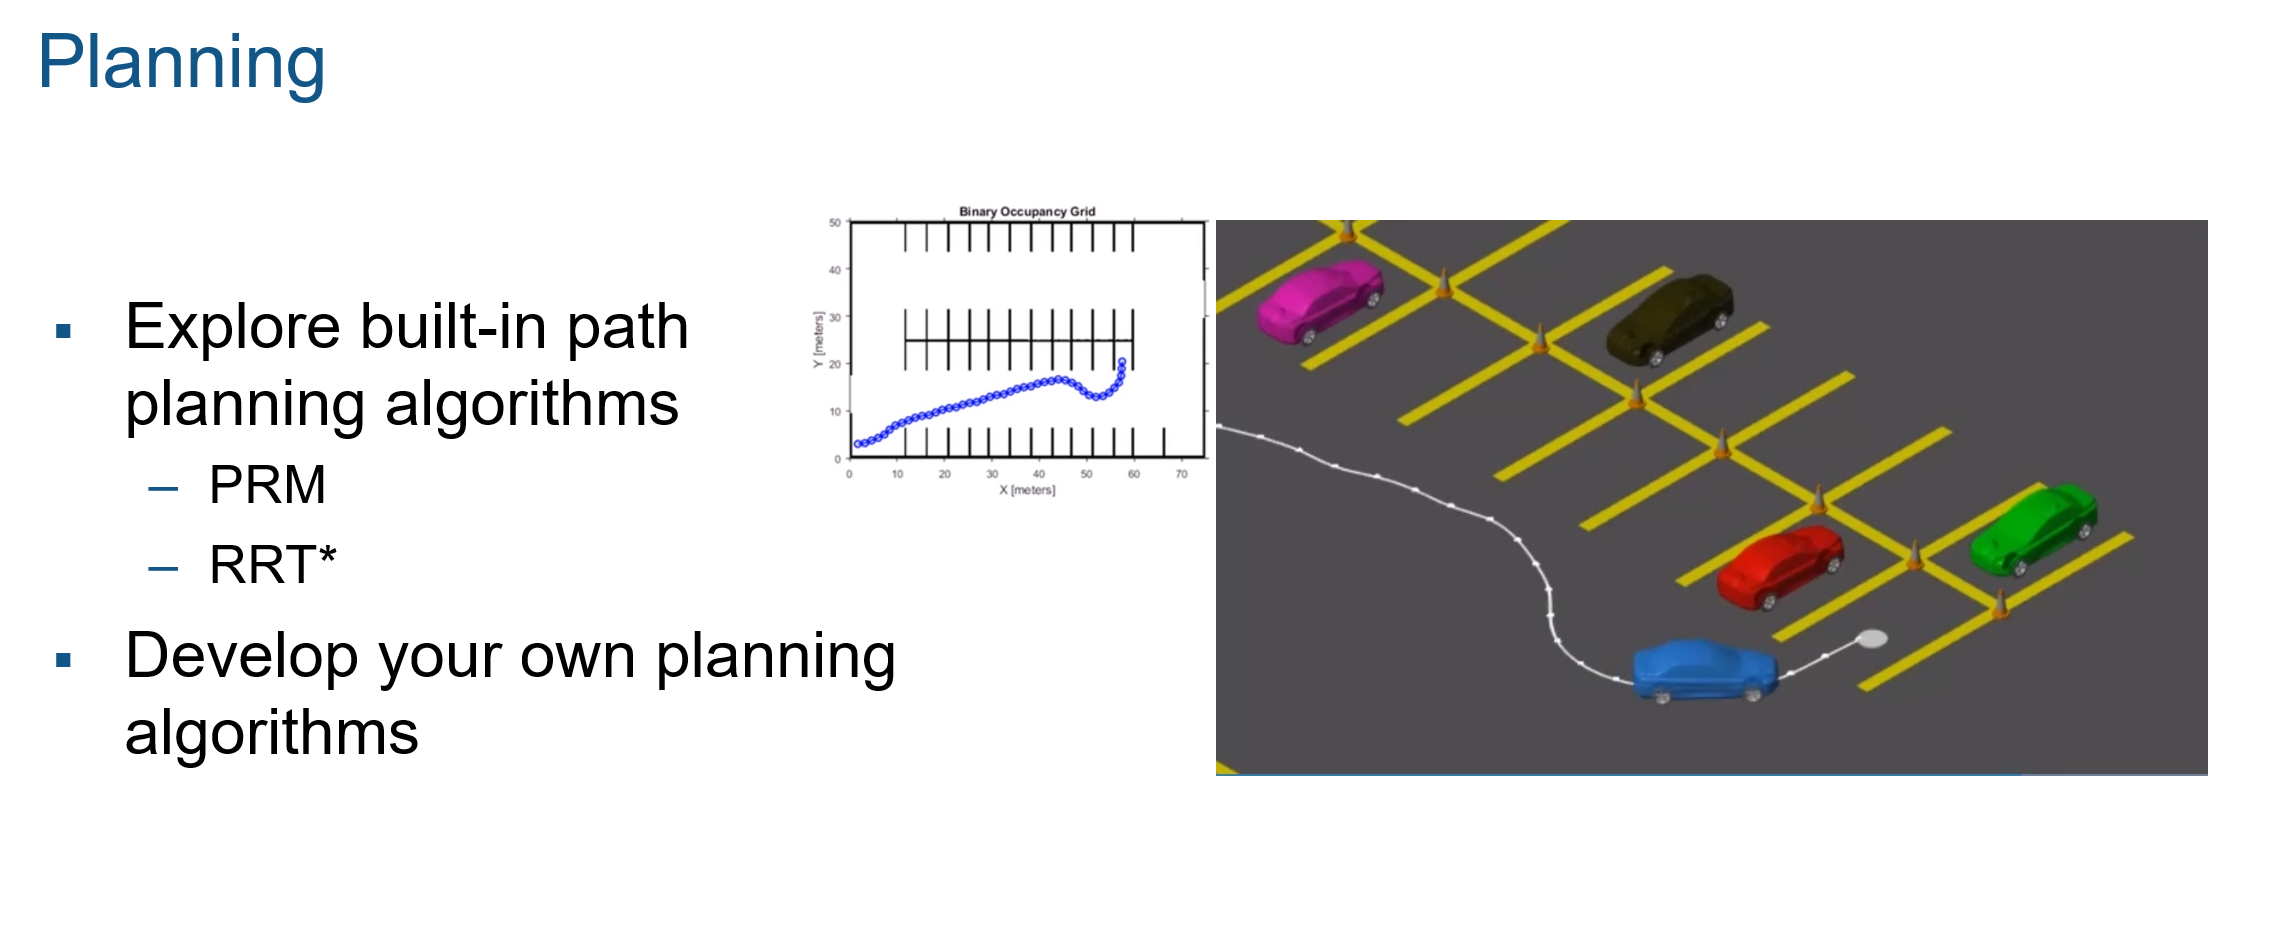

## Connecting MATLAB/Simulink to ROS

`rosinit` starts the global ROS node with a default MATLAB® name and tries to connect to a ROS master running on `localhost` and port `11311`. If the global ROS node cannot connect to the ROS master, `rosinit` also starts a ROS core in MATLAB, which consists of a ROS master, a ROS parameter server, and a rosout logging node.

rosshutdown
rosinit 192.168.137.134
% rosinit 192.168.1.127

## Load generated occupancy grid

`show(`[`map`](https://www.mathworks.com/help/nav/ref/occupancymap.show.html#mw_472ec64f-07a7-4bc7-bd8b-8834c236c0cb_sep_bvaw7ti-1-map)`)` displays the occupancy grid `map` in the current axes, with the axes labels representing the world coordinates.

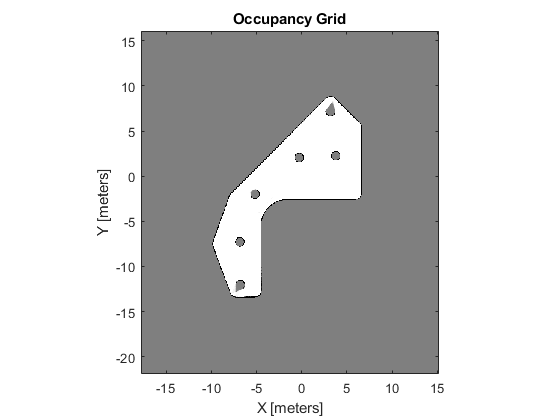

load("Walker_Interior_OccGrid.mat", "myOccMap");
show(myOccMap)

## Set the start and goal poses

start = [0.0, 0.0, 0];
goal = [-7, -10, -pi];

## Show the start and goal positions of the robot

hold on
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')

## Show the start and goal headings

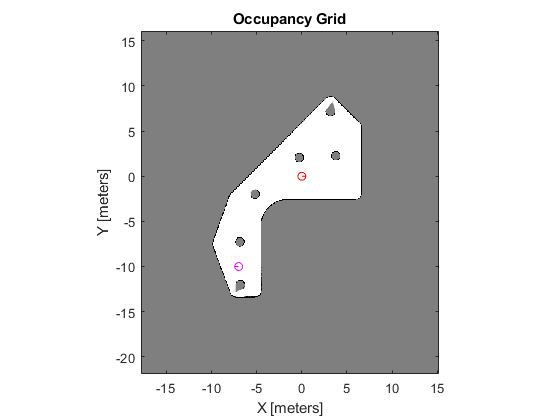

r = 0.5;
plot([start(1), start(1) + r*cos(start(3))], [start(2), start(2) + r*sin(start(3))], 'r-' )
plot([goal(1), goal(1) + r*cos(goal(3))], [goal(2), goal(2) + r*sin(goal(3))], 'm-' )
hold off

## Setup RRTplanner  

Create a Dubins state space and set the minimum turing readius to `0.2`. The `stateSpaceDubins` object stores parameters and states in the Dubins state space, which is composed of state vectors represented by [*x*, *y*, *θ*]. *x* and *y* are Cartesian coordinates, and *θ* is the orientation angle. The Dubins state space has a lower limit on the turning radius (specified by the `MinTurningRadius` property in the object) for navigating between states and uses the shortest feasible curve to connect states.

bounds = [myOccMap.XWorldLimits; myOccMap.YWorldLimits; [-pi pi]];
ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.3;

Create an `occupanyMap`-based state validator using the created state space. Set validation distance for the validator.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = myOccMap;
stateValidator.ValidationDistance = 0.1;

Create the path planner, selected max connection distance, max iterations and goal reached function

planner = plannerRRT(ss, stateValidator);
planner.MaxConnectionDistance = 3.0;
planner.MaxIterations = 1000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan a path with default settings.

rng(4,'twister'); % for repeatable result
[pthObj, solnInfo] = plan(planner, start, goal);

## Visualize the results

`show(`[`map`](https://www.mathworks.com/help/nav/ref/occupancymap.show.html#mw_472ec64f-07a7-4bc7-bd8b-8834c236c0cb_sep_bvaw7ti-1-map)`)` displays the occupancy grid `map` in the current axes, with the axes labels representing the world coordinates.

show(myOccMap)
hold on

Display Search tree

plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');

Interpolate and plot path

interpolate(pthObj,30)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)

Show the start and goal in the grid map

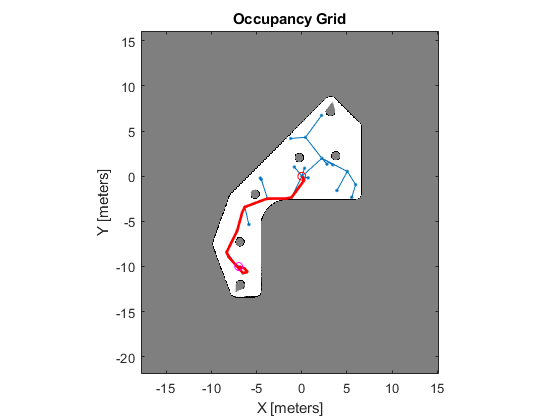

plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

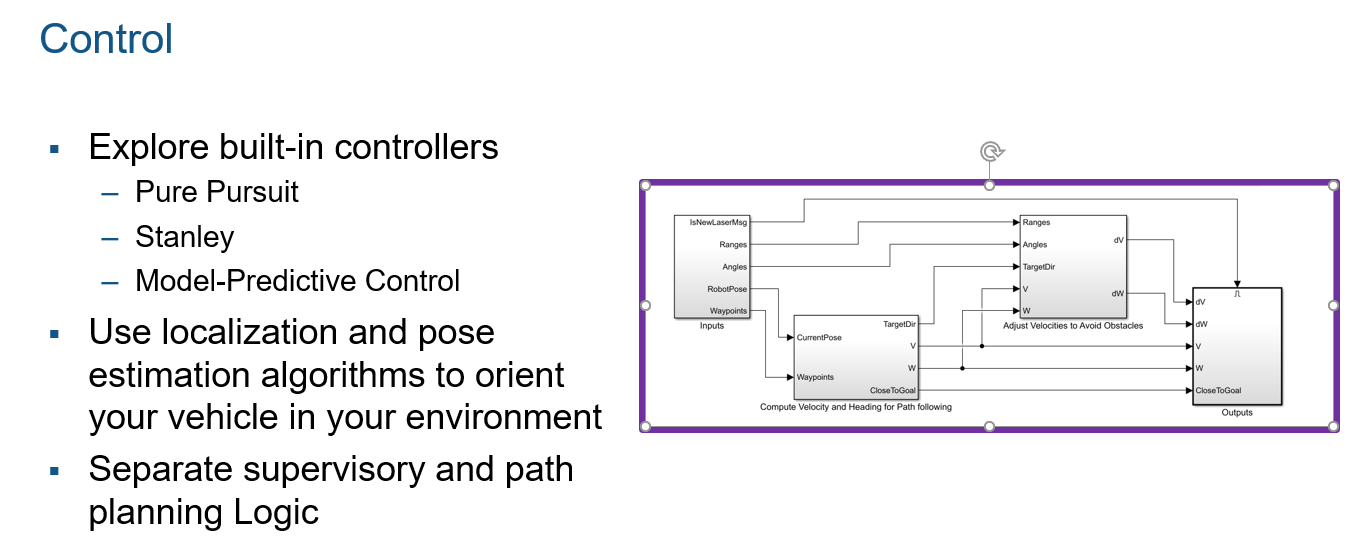

%run Mod_pose
open_system('PathFollowing_PurePursuit');

open_system('pathFollowingWithObstacleAvoidanceExample')

## Get Updated Pose

[msSub] = rossubscriber('/gazebo/model_states');
masterHost = '192.168.137.134';
clear poseMCL
poseMCL = ros.Node('poseMCL', masterHost);
mclPub = ros.Publisher(poseMCL,'/poseMCL','geometry_msgs/PoseWithCovariance');
mclMsg = rosmessage(mclPub);

while(1)

msSub.LatestMessage;

mclMsg.Pose.Position.X = msSub.LatestMessage.Pose(2).Position.X;
mclMsg.Pose.Position.Y = msSub.LatestMessage.Pose(2).Position.Y;
mclMsg.Pose.Position.Z = msSub.LatestMessage.Pose(2).Position.Z;
mclMsg.Pose.Orientation.X = msSub.LatestMessage.Pose(2).Orientation.X;
mclMsg.Pose.Orientation.Y = msSub.LatestMessage.Pose(2).Orientation.Y;
mclMsg.Pose.Orientation.Z = msSub.LatestMessage.Pose(2).Orientation.Z;
mclMsg.Pose.Orientation.W = msSub.LatestMessage.Pose(2).Orientation.W;
send(mclPub,mclMsg);
end